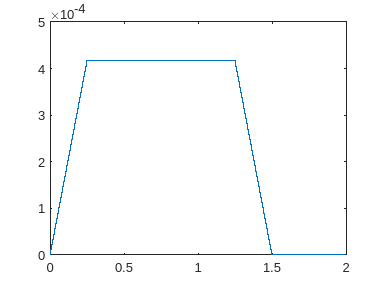

clc; clear all; close all;

g = 9.81; % m/s^2
d = 42/1000; % m
dr = 30/1000; % m
L0 = 1600/1000; % m
m1 = 3000; % kg
m2 = 5000; % kg

Ff1max = 12000; % N
Ff2max = 20000; % N
x1DotMax = 0.05; % m/s
x2DotMax = 0.05; % m/s

Cd = 0.6;

Ad1 = 9/10^6; % m^2
Ad3 = Ad1; % m^2
Ad2 = 5/10^6; % m^2
Ad4 = Ad2; % m^2

rho = 875; % kg/m^3
beta = 830*10^6; % Pa

tr = 0.25; % s
Q0max = 25/(60*10^3); % m^3/s

x1 = 0.2; % m
x2 = x1; % m
x1Dot = 0; % m/s
x2Dot = 0; % m/s

t = 0; % s
dt = 10^-5; % s
idx = 1;
simTime = 2; % s

p0 = 0; % Pa
p1 = 0; % Pa
p2 = 0; % Pa
p3 = 0; % Pa
p4 = 0; % Pa

x1Dot = -15*x1DotMax;
x2Dot = -15*x2DotMax;

while(t <= simTime)
    % Calculations

    if(x1Dot < -x1DotMax)
        Ff1 = -Ff1max;
    elseif(x1Dot < x1DotMax)
        Ff1 = x1Dot/x1DotMax * Ff1max;
    else
        Ff1 = Ff1max;
    end

    if(x2Dot < -x2DotMax)
        Ff2 = -Ff2max;
    elseif(x2Dot < x2DotMax)
        Ff2 = Ff2max/x2DotMax * x2Dot;
    else
        Ff2 = Ff2max;
    end

    if(t <= tr)
        Q0 = t/tr * Q0max;
    elseif(t < tr+1)
        Q0 = Q0max;
    elseif(t < 1.5)
        tm = t-(1.5-0.25);
        Q0 = Q0max * (1-(tm/0.25));
    else
        Q0 = 0;
    end
        

    % Logging
    tplt(idx) = t;
    Ff1plt(idx) = Ff1;
    Ff2plt(idx) = Ff2;
    qplt(idx) = Q0;
    x1plt(idx) = x1;
    x2plt(idx) = x2;
    p0plt(idx) = p0;
    p3plt(idx) = p3;
    p4plt(idx) = p4;

    % Time integration
    

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

% plot(tplt, Ff1plt)
% hold off
% plot(tplt, Ff2plt)
plot(tplt, qplt)